# Problema 3 

Un dipòsit a pressió $p_0$ que conté nitrogen líquid té les dimensions que mostra la figura. El líquid assoleix una altura vertical de 2m sobre el fons del dipòsit. El dipòsit es pot considerar com un cilindre horitzontal.

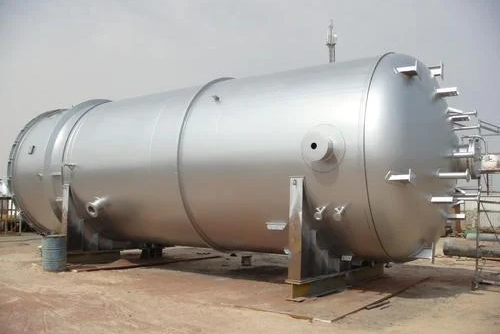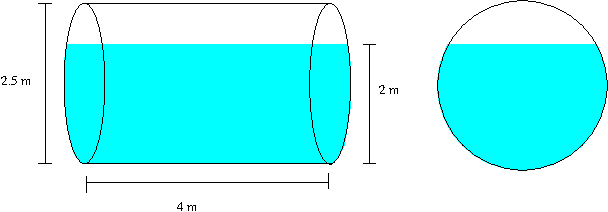

**a)  Calcula la força resultant sobre les tapes del cilindre, considerades com a superfícies planes:**

**    a1) La deguda exclusivament als 2m de nitrogen líquid (vol dir, sense tenir en compte **$p_0$**) (0.5P).**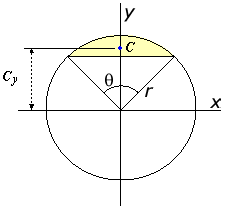

Àrea i posició del centroide d'un segment circular: 

Àrea = $\displaystyle \frac{r^2}{2}\; (\theta - \sin\theta)$


$$C_y = \displaystyle \frac{4r}{3}\; \left(\frac{\sin^3 \theta/2}{\theta - \sin \theta}   \right)$$


D=2.5; H=2; r=D/2; L=4;
theta= 2*acos((r-(D-H))/r); fprintf('theta=%5.2fº\n',theta*180/pi)

theta=106.26º


Aquest angle és el de l'àrea en groc de la figura, però la que ens interessa és l'altra que queda, la de la porció més grran, no la groga. Per trobar $C_y$ de la porció que volem,  el més fàcil es restar l'angle theta que hem trobat de 360º, perquè la fórmula de $C_y$ és vàlida per a qualsevol angle, ja sigui  major o menor que $\pi$. 

theta = 2*pi-theta

theta = 4.4286

en rad, i el centroide $C_y$:

Cy= 4*r/3 *sin(theta/2)^3/(theta-sin(theta))

Cy = 0.1584

en metres. Compte perquè $C_y$ està referit a un sistema de coordenades centrat en el cercle, no a la superíicie lliure, i per al càlcul de les forces amb les fórmules per a les superfícies planes, l'altura $h_G$ del centroide està referida a la superfície lliure del líquid. A sobre, l'àrea de la figura que volem queda invertida respecte del tanc,

                                      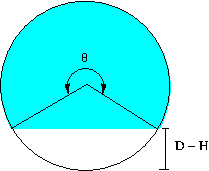

 i la referència de la posició del centroide també. Si la girem, 

                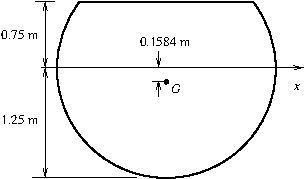

Així doncs,

hG = Cy + r -(D-H)

hG = 0.9084

es la profunditat (en m) on se situa el centroide de l'àrea de qualsevol de les tapes del tanc mullades pel nitrògen.

També necessitem la superfície del nostre segment circular, donat por la fórmula


$$A = \frac{r^2}{2} \, (\theta - \sin \theta)$$


A = r^2/2*(theta - sin(theta)) %m²

A = 4.2098

Finalment apliquem la fórmula de la força sobre una superfície plana submergida: $F = \rho g h_G A$ 

rho = 798.6; %densitat del nitrògen
g = 9.81;
F = rho*g*hG*A

F = 2.9959e+04

   la força F està en (N).

**a2) Ara només tenint en compte **$p_0$** i no el nitrogen líquid, calcula la resultant de les forces de pressió **$p_0$** sobre la paret circular. On s'aplica aquesta resultant? (fes-ne un dibuix) (0.5P).**

Les forces de pressió $p_0$ es deuen a la pressión dins del tanc, y les exerceix el nitrògen gasós o l'aire que hi hagi en equilibri amb el nitrògen líquid. Actuen sobre **tota** la superíicie circular, i s'apliquen al centre del cercle (al contrari que les forces de pressió degudes al nitrògen líquid, que s'apliquen a una profunditat de $h_p = h_G + \frac{ I_{xG} \sin^2 90º}{h_G A}$ respecte de la superfície lliure)

p0 = 122e3; %sobrepressió a l'interior del tanc
F = p0* pi*r^2

F = 5.9887e+05

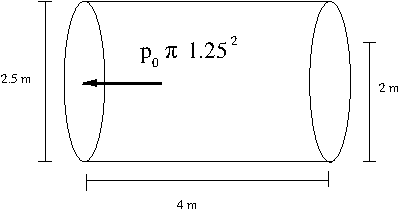

Per cert que, comparant amb el resultat de l'apartat a1, podem concloure que en un tanc a pressió, les forces degudes a $p_0$ poden considerar-se de seguida com a dominants (122 kPa no és una sobrepressió molt gran comparat amb les que s'utilitzen a la indústria dels gasos, però representen ja 12 m de columna d'aigua), i en canvi, les degudes a la altura de líquid solen ser menys importants.

**b) Suposem que el tanc està compost de dos semicilindres units entre sí. Calcula la força de pressió sobre cada superfície semicilíndrica:**

**b1) Utilitzant el volum de control de la figura, calcula les components de la força resultant de pressió sobre el semicilindre de la dreta deguda exclusivament a l'altura del nitrogen líquid dins del tanc (és a dir, sense **$p_0$**) (0.5P).**

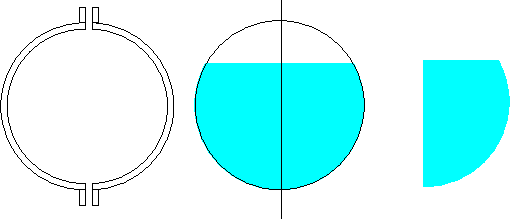 $V$

Sense tenir en compte $p_0$, sobre el volum auxiliar $V$ de la dreta actuen les forces següents:

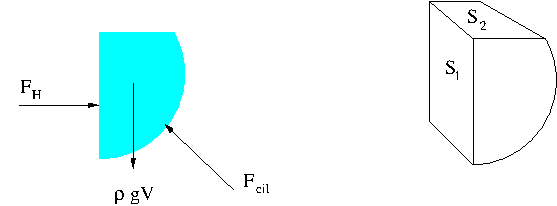

La força $F_{cil}$  és la que la superfície semicilíndrica del tanc exerceix sobre la porció auxiliar $V$, i és la mateixa en valor però de sentit contrari a la que exerceix la porció $V$ de fluid sobre la superíicie sòlida. 

Com que el volum $V$ està en equilibri, la component horitzontal de $F_{cil}$ es la pròpia $F_H$ (equilibri de forces).

Per calcular $F_H$ no considerem la contribució de $p_0$, segons diu l'enunciat:

$F_H = \rho g h_G S_1$, donde $h_G$ es **ara** la profunditat del centroide de la superfície plana $S_1$, d'alçada $H=2$m i amplada $L=4$m

S1 = H*L;
hG = H/2;
FH = rho*g*hG*S1

FH = 6.2674e+04

en N. Aquesta força s'aplica a una profunditat, comptada des de la superfície lliure,


$$h_P = h_G + \frac{\rho g I_{Gx} \sin \theta }{F_H}$$


IGx = L*H^3/12;
hP=hG + rho*g*IGx*1/FH

hP = 1.3333

m (en realitat, no cal cap càlcul: dona $h_P=2H/3$, com correspon al rectangle vertical submergit, ja ho sabem pels problemes de classe). Tampoc ens demanaven calcular-la. Per tant, $F_{cil, x}=F_H$ és la força horitzontal que el nitrògen líquid exerceix sobre la paret semicíindrica, aplicada a 

H-hP

ans = 0.6667

en (m) des de la base del tanc.

 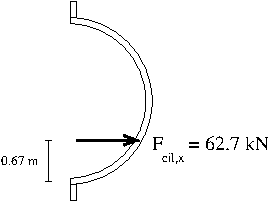

La component vertical $F_{cil, y}$, sense tenir en compte $p_0$, és el pes $F_V=\rho g V$ del volum $V$. 

V = L*A/2

V = 8.4197

(m³).  Aquí l'área $A$ és la de l'apartat a1, dividida per 2.

FV = rho*g*V

FV = 6.5962e+04

en (N). Aquesta força actua en la línea d'acció que passa pel centroide de la porció $V$, tampoc ens demanen fer-ne el càlcul explícitament. Podem representar esquemàticament la fuerza vertical $F_{cil,y} = F_V$ que suporta cada paret semililíndrica com

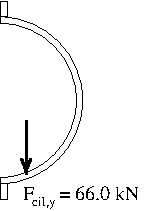

**b2) On s'aplica, i quina direcció i sentit té, la resultant de les forces de pressió sobre el semicilindre de la dreta degudes a l'altura de nitrogen líquid? (fes dibuixos i calcula l'angle d'orientació) (0.5P).**

Com que les forces de pressió són normals a la superfície en cada punt i aquesta té geometria cilíndrica, totes les línies d'acció passen per l'eix del cilindre i la resultant també (la resultant d'un sistema de vectors concurrents en un punt, passa pel punt de concurrència).

alfa = atan (FV/FH) * 180/pi %deg

alfa = 46.4641

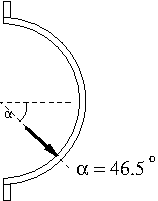

**b3) Ara prescindint del nitrogen líquid, quant val, on s'aplica, i quina direcció i sentit té, la resultant de les forces de pressió **$p_0$** sobre el semicilindre de la dreta?  (0.5P).**

Als dos apartats anteriors hem prescindit del càlcul de les forces de pressió al tanc degudes a $p_0$, perquè de fet ja sabem on actuen i quin valor tenen aquestes: la pressió és uniforme i  s'exerceix sobre **tota** la superfície del tanc, sobre cada semicilindre valen $p_0 D L$ i s'apliquen horitzontalment sobre cada paret semicilíndrica, passant pel centre del cilindre. 

Sobre el semicilindre de la dreta tindríem 

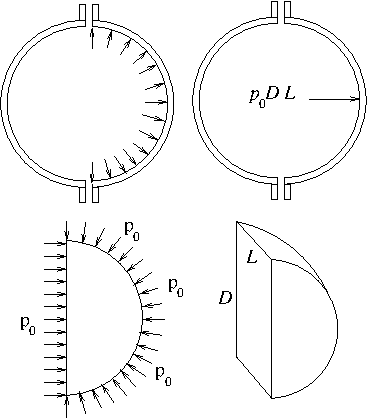

A baix, volum auxiliar de fluid (medi imaginari) a pressió uniforme $p_0$ 

amb D=2.5 m y L = 4m.

p0*D*L 

ans = 1220000

en (N). Comparant aquest valor amb el del pas del nitrògen líquid, novament veiem que de seguida les forces degudes a la sobrepressió en un tanc són les més importants, sobretot si no hi ha grans alçades de líquid a dins.